# Lactose Utilization Network of *Escherichia Coli *

% ensure that glucose concentration is >10 for beta_g to be valid.
% concentrations are expressed in uM.
consts.glu = 60;
consts.tmg_e = 100;

% total LacI conc.
consts.rT = 0.4e-3;

% model params.
params.rho = 167.1;
params.beta_g = 65;
params.n = 2;

### Analytical Solution for Steady State

ode_funcs = lac_system_ode;
[ode_tmgi_nullcline, ode_lacy_nullcline] = ode_funcs.nullclines(consts, params);
% plot nullclines.
close all; figure; hold on; zoom on;
plot(double(subs(ode_tmgi_nullcline, sym('lac_y'), linspace(0, 40, 81))), 0:0.5:40);
plot(0:0.5:40, double(subs(ode_lacy_nullcline, sym('tmg_i'), linspace(0, 40, 81))));
title('Phase Plot');
xlabel('Intracellular TMG (\muM)');
ylabel('LacY (\muM)');

Obtain the points of intersection.

[ode_tmgi_nulleqn, ode_lacy_nulleqn] = ode_funcs.nulleqns(consts, params);
soln = solve([ode_tmgi_nulleqn, ode_lacy_nulleqn], [sym('lac_y'), sym('tmg_i')]);
for i=1:length(soln.lac_y)
    scatter(soln.tmg_i(i), soln.lac_y(i), "filled");
    disp(double([soln.tmg_i(i), soln.lac_y(i)]));
end

    0.1809    0.1427

    7.4936    5.9139

   21.5969   17.0440



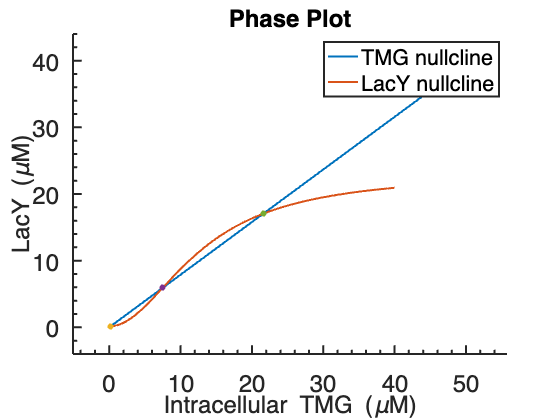

legend('TMG nullcline', 'LacY nullcline', '', '', '');
hold off; PrettyFig;

**Simulate ODE; **export simulated data to add noise and then infer: **Data 1.**

% time duration.
consts.tmax = 50;

% get ODE functions.
ode_funcs = lac_system_ode;

figure; hold on; zoom on;
% initial concentrations.
consts.y_init = [0; 36];

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

Unpack and Plot the ODE solutions.

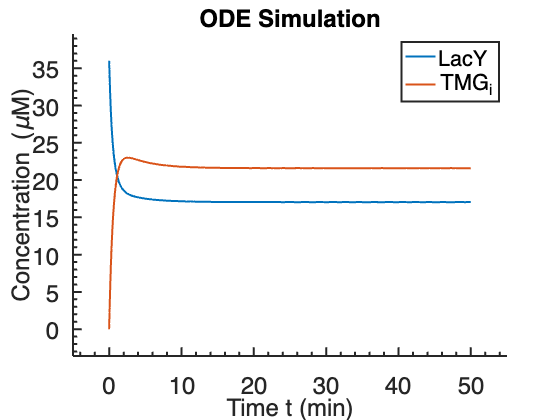

% unpack.
ode_tmgi = x(:, 1);
ode_lacy = x(:, 2);

% plot.
plot(ode_tout, ode_lacy, 'DisplayName', sprintf("LacY"));
plot(ode_tout, ode_tmgi, 'DisplayName', sprintf("TMG_i"));
legend();
title('ODE Simulation');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
PrettyFig;
hold off; shg;

Export the ODE simulation.

writematrix(cat(2, ode_tout, ode_lacy), "data/lacy_at_init_36.csv");
writematrix(cat(2, ode_tout, ode_tmgi), "data/tmgi_at_init_36.csv");

**Simulate ODE; **export simulated data to add noise and then infer: **Data 2.**

% time duration.
consts.tmax = 50;

% get ODE functions.
ode_funcs = lac_system_ode;

figure; hold on; zoom on;
% initial concentrations.
consts.y_init = [0; 6];

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

Unpack and Plot the ODE solutions.

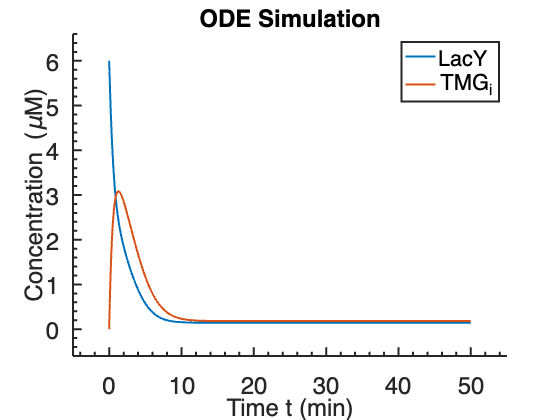

% unpack.
ode_tmgi = x(:, 1);
ode_lacy = x(:, 2);

% plot.
plot(ode_tout, ode_lacy, 'DisplayName', sprintf("LacY"));
plot(ode_tout, ode_tmgi, 'DisplayName', sprintf("TMG_i"));
legend();
title('ODE Simulation');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
PrettyFig;

Export the ODE simulation.

writematrix(cat(2, ode_tout, ode_lacy), "data/lacy_at_init_6.csv");
writematrix(cat(2, ode_tout, ode_tmgi), "data/tmgi_at_init_6.csv");

**Solve the system of ODEs for different initial concentrations of LacY.**

% time duration.
consts.tmax = 50;

% get ODE functions.
ode_funcs = lac_system_ode;

% save ODE results.
lacy_inits = 0:4:40;

figure; hold on; zoom on;
% initial concentrations.
for i=1:length(lacy_inits)
    
    lacy_init = lacy_inits(i);
    consts.y_init = [0; lacy_init];
    % solve ODE.
    [ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

Unpack and Plot the ODE solutions.

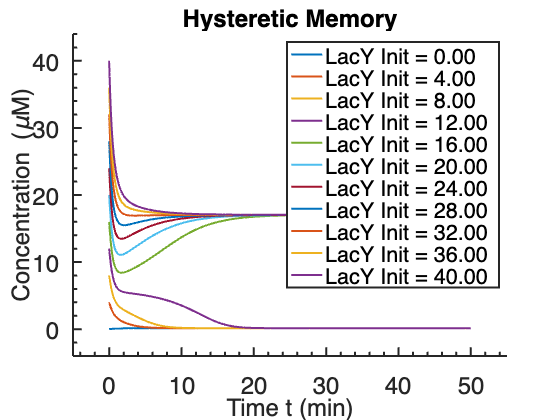

    % unpack.
    ode_tmgi = x(:, 1);
    ode_lacy = x(:, 2);
    
    % plot.
    plot(ode_tout, ode_lacy, 'DisplayName', sprintf("LacY Init = %.2f", lacy_init));
end
title('Hysteretic Memory');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
legend();
PrettyFig;

**Solve the system of ODEs for different initial concentrations of LacY -- Uninduced Monostability caused by very low Extracellular TMG.**

consts.glu = 50;
consts.tmg_e = 1;

Analytical solution.

ode_funcs = lac_system_ode;
[ode_tmgi_nullcline, ode_lacy_nullcline] = ode_funcs.nullclines(consts, params);
% plot nullclines.
figure; hold on; zoom on;
solve_vals_x = 0:1:50;
solve_vals_y = 0:1:400;
plot(double(subs(ode_tmgi_nullcline, sym('lac_y'), solve_vals_x)), solve_vals_x);
plot(solve_vals_y, double(subs(ode_lacy_nullcline, sym('tmg_i'), solve_vals_y)));
title('Phase Plot');
xlabel('Intracellular TMG (\muM)');
ylabel('LacY (\muM)');

% obtain the points of intersection.
[ode_tmgi_nulleqn, ode_lacy_nulleqn] = ode_funcs.nulleqns(consts, params);
soln = solve([ode_tmgi_nulleqn, ode_lacy_nulleqn], [sym('lac_y'), sym('tmg_i')], 'Real', true);
for i=1:length(soln.lac_y)
    scatter(soln.tmg_i(i), soln.lac_y(i), "filled");
    disp(double([soln.tmg_i(i), soln.lac_y(i)]));
end

    0.0118    0.1475



legend('TMG nullcline', 'LacY nullcline', '', '', '');

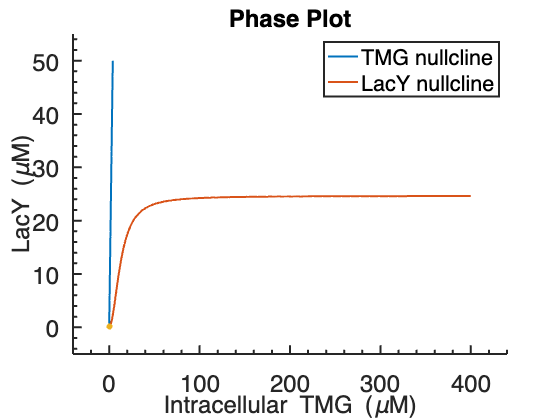

PrettyFig;

**The system has only one stable state here, at LacY ~ 0.14 uM.**

ODE Simulation for different starting concentrations of LacY.

% time duration.
consts.tmax = 50;
% get ODE functions.
ode_funcs = lac_system_ode;
% save ODE results.
lacy_inits = [0 4 8 40 50 60];

figure; hold on; zoom on;
% initial concentrations.
for i=1:length(lacy_inits)
    
    lacy_init = lacy_inits(i);
    consts.y_init = [0; lacy_init];
    % solve ODE.
    [ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

Unpack and Plot the ODE solutions.

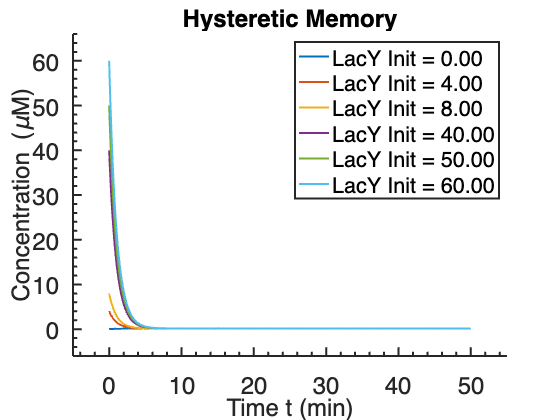

    % unpack.
    ode_tmgi = x(:, 1);
    ode_lacy = x(:, 2);
    
    % plot.
    plot(ode_tout, ode_lacy, 'DisplayName', sprintf("LacY Init = %.2f", lacy_init));
end
title('Hysteretic Memory');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
legend();
PrettyFig;

**Solve the system of ODEs for different initial concentrations of LacY -- Induced Monostability caused by very high extracellular TMG at low Glucose.**

consts.glu = 15;
consts.tmg_e = 1000;

Analytical solution.

ode_funcs = lac_system_ode;
[ode_tmgi_nullcline, ode_lacy_nullcline] = ode_funcs.nullclines(consts, params);
% plot nullclines.
figure; hold on; zoom on;
solve_vals_x = 0:1:50;
solve_vals_y = 0:1:400;
plot(double(subs(ode_tmgi_nullcline, sym('lac_y'), solve_vals_x)), solve_vals_x);
plot(solve_vals_y, double(subs(ode_lacy_nullcline, sym('tmg_i'), solve_vals_y)));
title('Phase Plot');
xlabel('Intracellular TMG (\muM)');
ylabel('LacY (\muM)');
% obtain the points of intersection.
[ode_tmgi_nulleqn, ode_lacy_nulleqn] = ode_funcs.nulleqns(consts, params);
soln = solve([ode_tmgi_nulleqn, ode_lacy_nulleqn], [sym('lac_y'), sym('tmg_i')], 'Real', true);
for i=1:length(soln.lac_y)
    scatter(soln.tmg_i(i), soln.lac_y(i), "filled");
    disp(double([soln.tmg_i(i), soln.lac_y(i)]));
end

  218.0294   43.2212



legend('TMG nullcline', 'LacY nullcline', '', '', '');

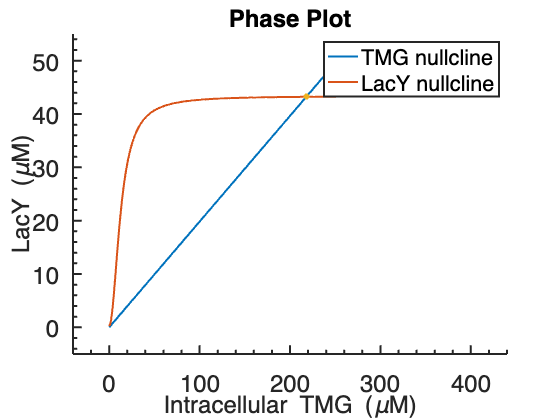

PrettyFig;

**The system has only one stable state here, at LacY ~ 43 uM.**

**ODE Simulation for different starting concentrations of LacY.**

% time duration.
consts.tmax = 50;
% get ODE functions.
ode_funcs = lac_system_ode;
% save ODE results.
lacy_inits = [0 4 8 40 50 60];

figure; hold on; zoom on;
% initial concentrations.
for i=1:length(lacy_inits)
    
    lacy_init = lacy_inits(i);
    consts.y_init = [0; lacy_init];
    % solve ODE.
    [ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

Unpack and Plot the ODE solutions.

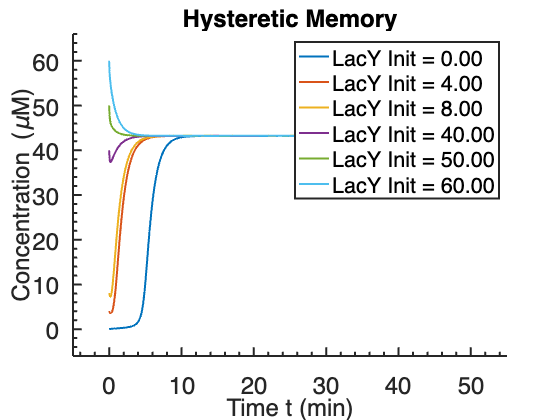

    % unpack.
    ode_tmgi = x(:, 1);
    ode_lacy = x(:, 2);
    
    % plot.
    plot(ode_tout, ode_lacy, 'DisplayName', sprintf("LacY Init = %.2f", lacy_init));
end
title('Hysteretic Memory');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
legend();
PrettyFig;

**Visualize the Stability Region as a Function of Extracellular Glucose and TMG**

[tmg_e_vals, gluc_vals] = meshgrid(0:10:1000,0:10:1000);
num_solns = zeros([length(gluc_vals) length(gluc_vals)]);
for i=1:length(gluc_vals)
    for j=1:length(gluc_vals)
        consts.glu = tmg_e_vals(i, j);
        consts.tmg_e = gluc_vals(i, j);
        ode_funcs = lac_system_ode;
        [ode_tmgi_nulleqn, ode_lacy_nulleqn] = ode_funcs.nulleqns(consts, params);
        % obtain the points of intersection.
        [ode_tmgi_nulleqn, ode_lacy_nulleqn] = ode_funcs.nulleqns(consts, params);
        soln = solve([ode_tmgi_nulleqn, ode_lacy_nulleqn], [sym('lac_y'), sym('tmg_i')], 'Real', true);
        num_solns(i, j) = length(soln.lac_y);
        % pause(1);
    end
end

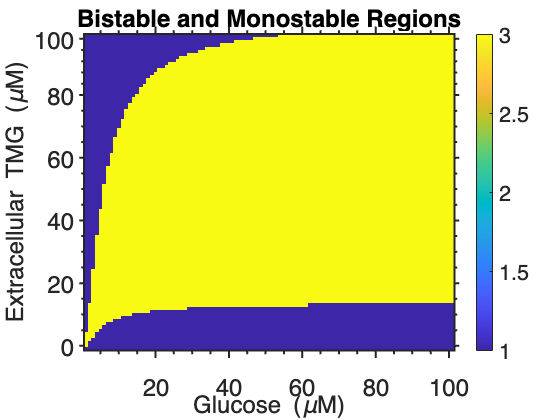

figure;
imagesc(flip(num_solns, 1));
colorbar();
title('Bistable and Monostable Regions');
xlabel('Glucose (\muM)');
ylabel('Extracellular TMG (\muM)');
yticks([2 20 40 60 80 100])
yticklabels({'100' '80','60','40','20','0'})
PrettyFig;